Lab2

Code available at [https://github.com/sugaE/RV22/tree/main/Lab2](https://github.com/sugaE/RV22/tree/main/Lab2)

**(Add Lab1 to "Set Path")**

**Task 1**

shakey = read_image('','shakey.150.gif');
load filters.mat		

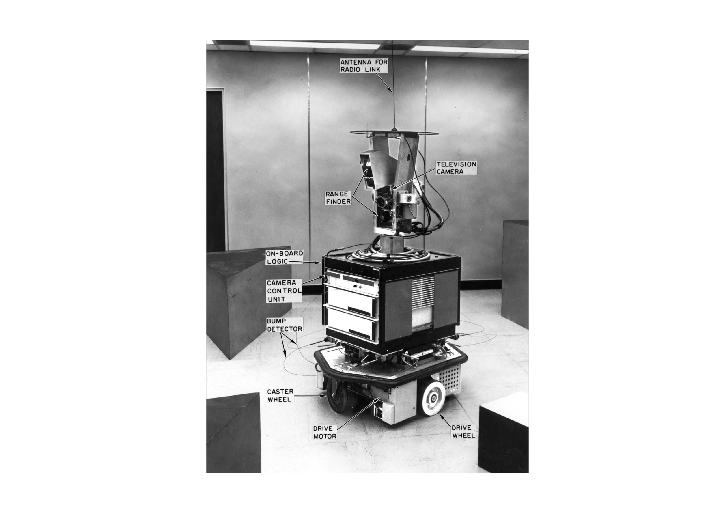

g3 = conv2(shakey, gaussian_filter_3x3, 'same');
g5 = conv2(shakey, gaussian_filter_5x5, 'same');
show_image(g3, 'g3');

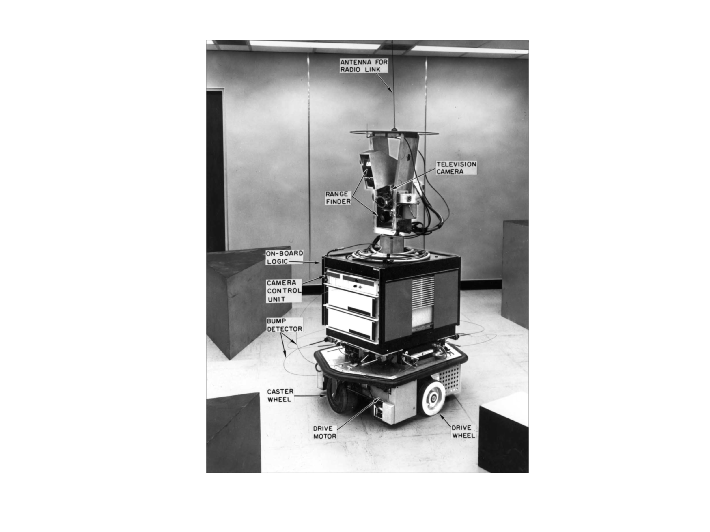

show_image(g5, 'g5');

i = 1

mean_last = 51.5307

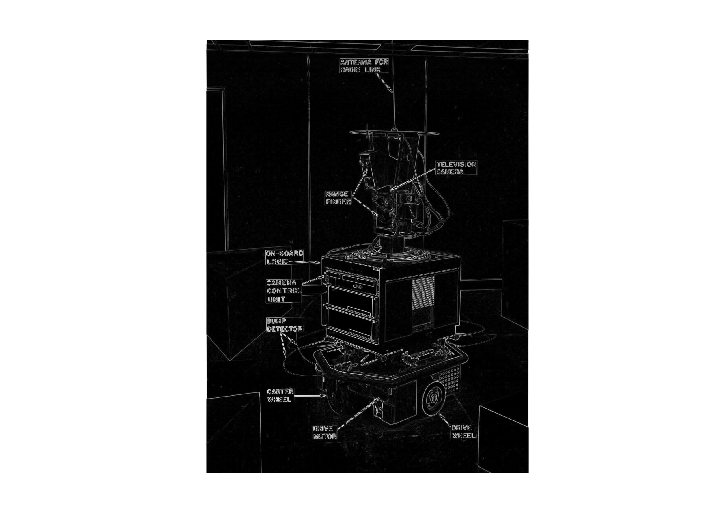

g1_sobel = task1(shakey, sobelX, sobelY, 0, 0, 'g1_sobel_'); % mean: 51.5

i = 1

mean_last = 47.5220

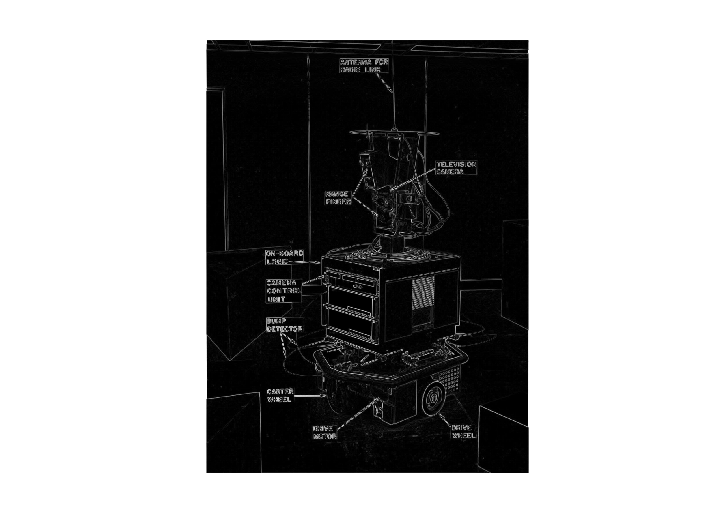

g3_sobel = task1(g3, sobelX, sobelY, 0, 0, 'g3_sobel_'); % mean: 47.5

i = 1

mean_last = 39.1404

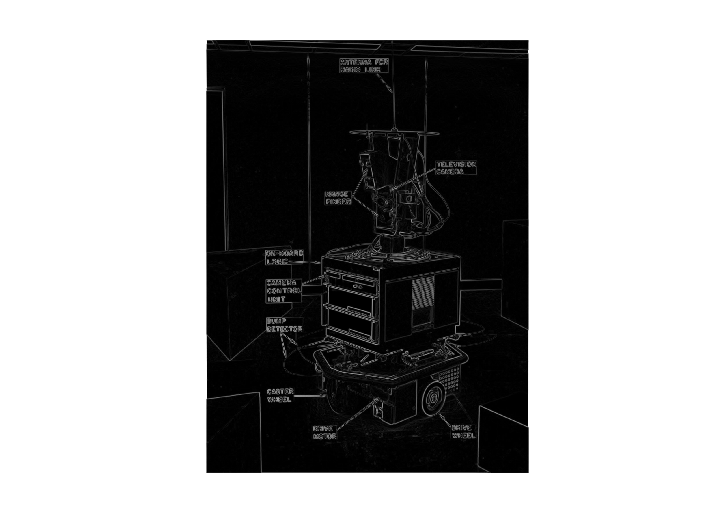

g5_sobel = task1(g5, sobelX, sobelY, 0, 0, 'g5_sobel_'); % mean: 39.1

**Can you describe the effect in comparison with applying the edge filter to the image directly? **

With size of the gaussian filters gets larger, the image gets blurer. Because larger size filter smoothes more pixels.

After applying edge filter, we can see the edge after 3*3 gaussian is stronger than 5*5's. Smaller gaussian filter size preserve more details and edges.

**Task 2 **

fname = "g3_std1"

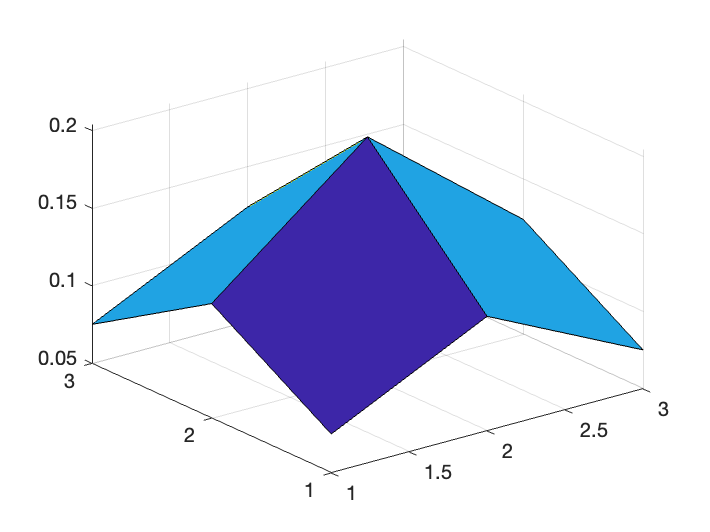

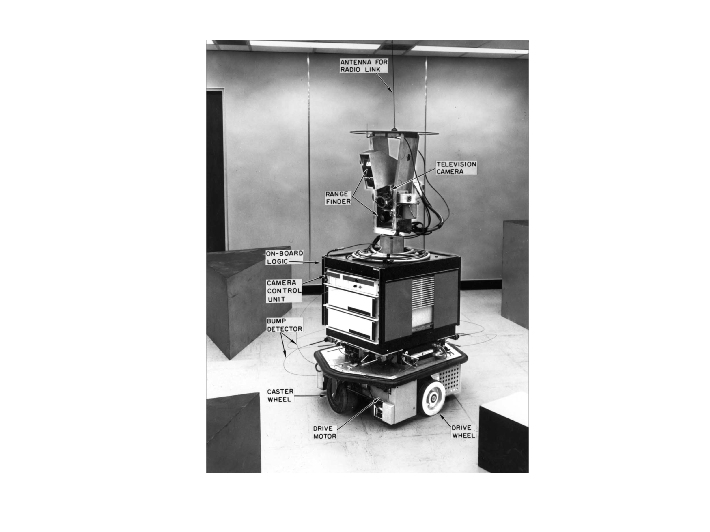

i = 1

mean_last = 42.5790

fname = "g5_std1"

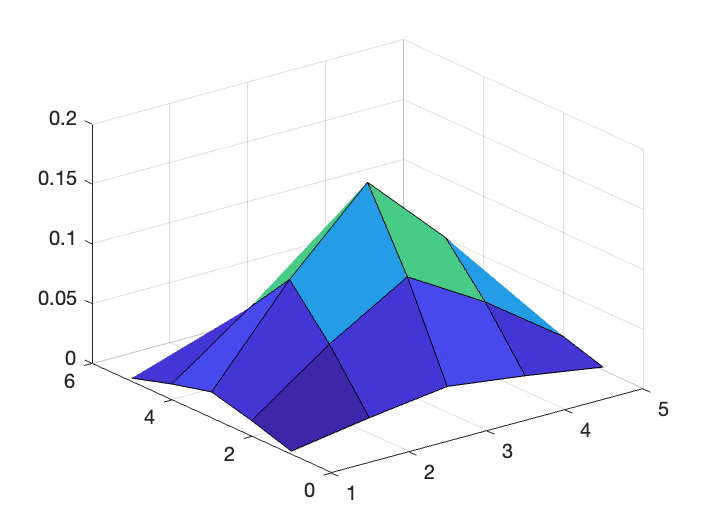

i = 1

mean_last = 39.1404

fname = "g7_std1"

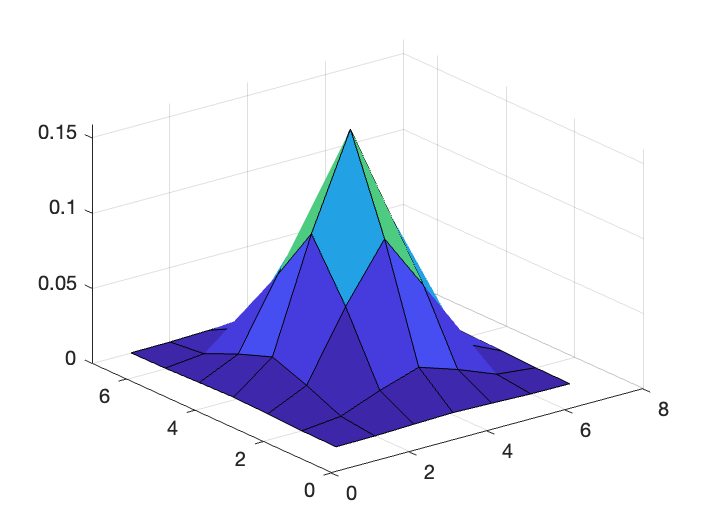

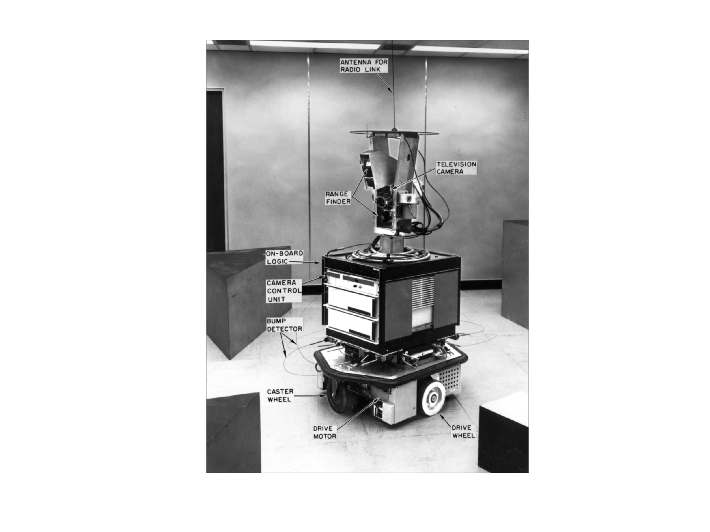

i = 1

mean_last = 38.7251

fname = "g9_std1"

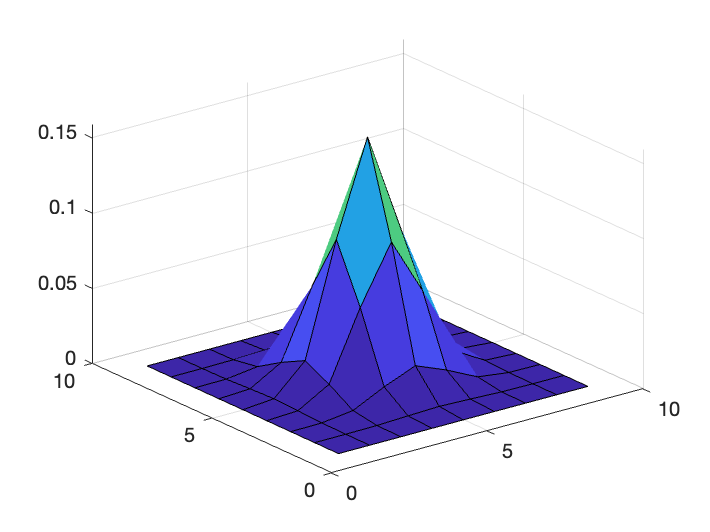

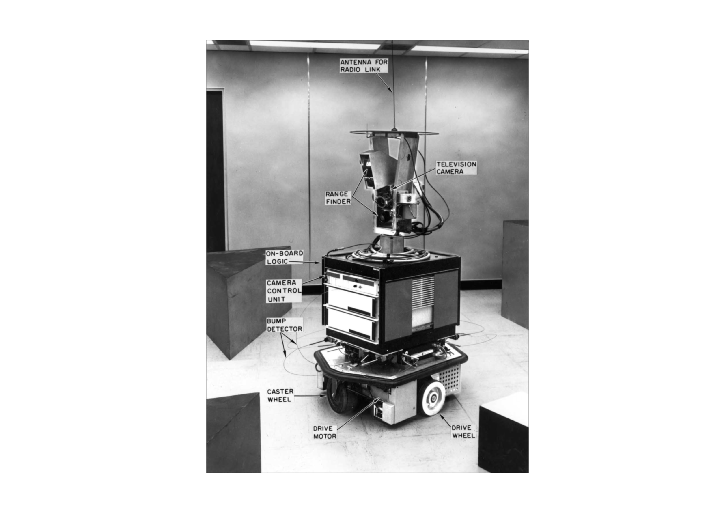

i = 1

mean_last = 38.7100

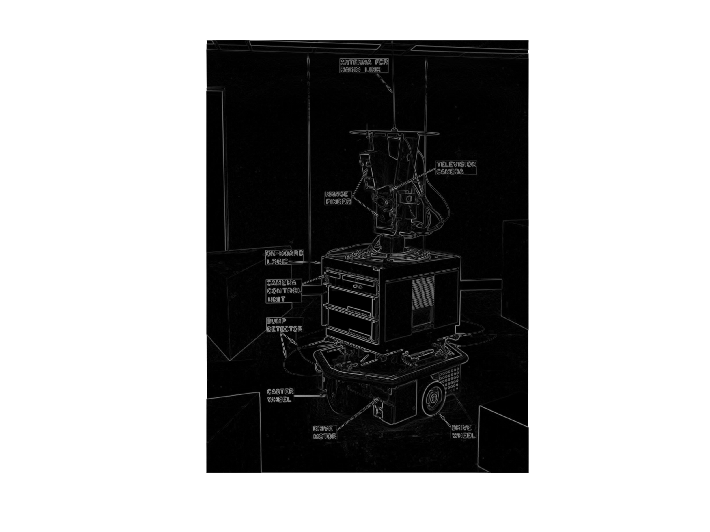

% fixed std=1; increasing size from 3 - 9
for i=(3:2:9)
    fname = "g" + num2str(i) + "_std1"
    g_n = gaussian_n(i, 1, 1); % == gaussian_filter_3x3 
    gn_conv = conv2(shakey, g_n, "same");
    show_image(gn_conv, fname);
    gn_sobel = task1(gn_conv, sobelX, sobelY, 0, 0, fname+ "_sobel_");
end  

fname = "g3_std0.5"

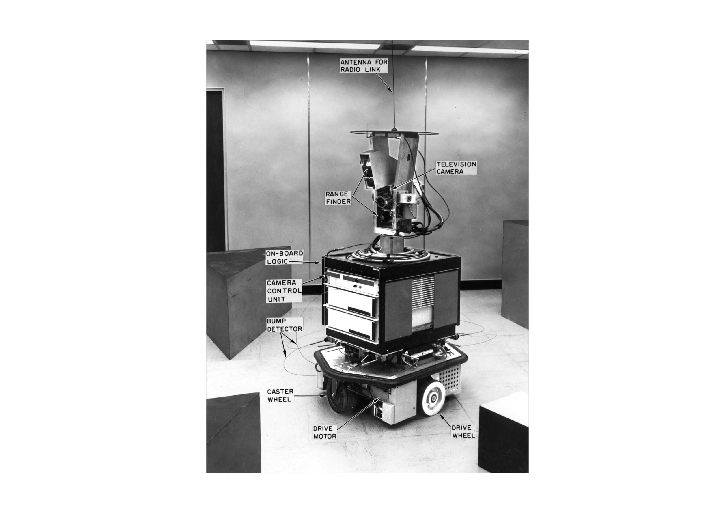

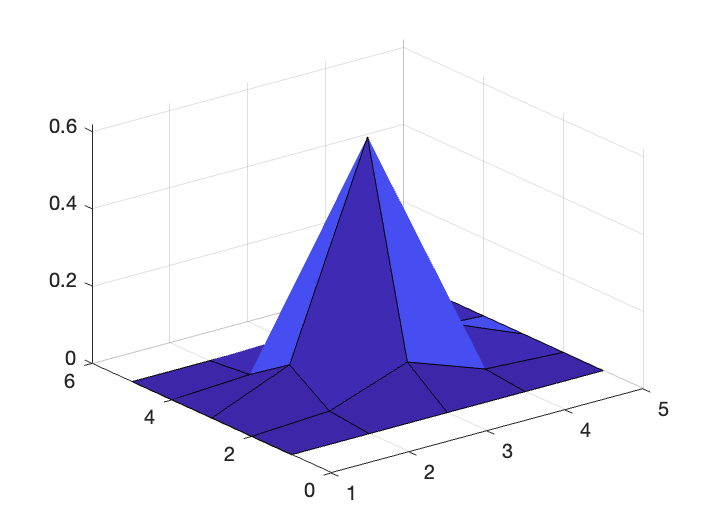

i = 1

mean_last = 47.4972

fname = "g3_std1"

i = 1

mean_last = 39.1404

fname = "g3_std1.5"

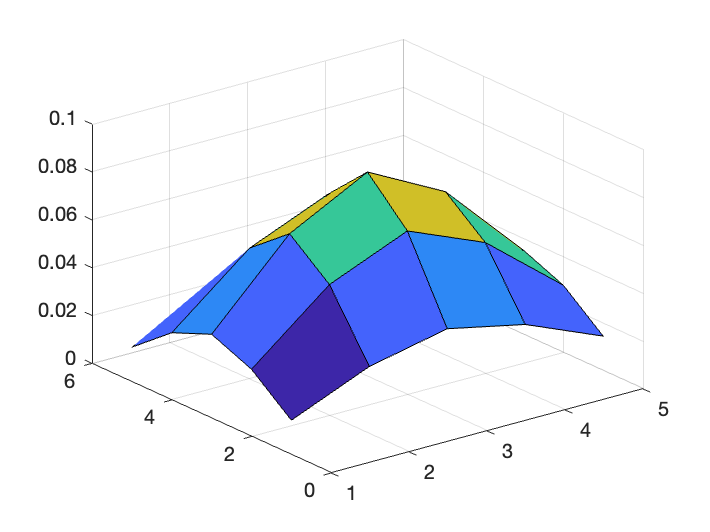

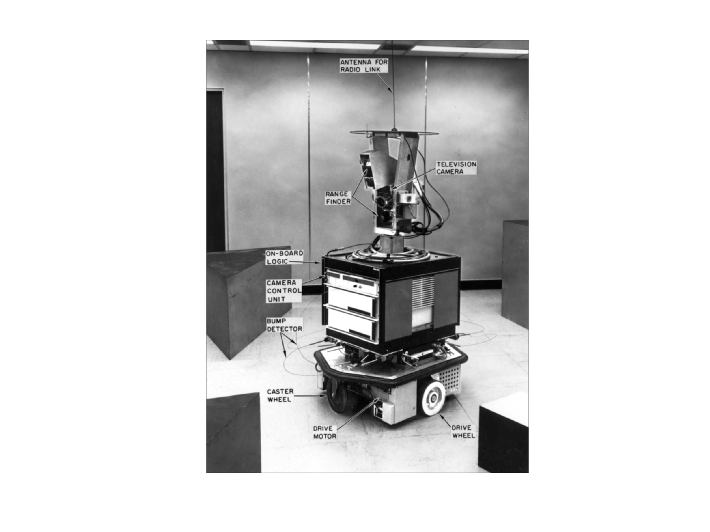

i = 1

mean_last = 35.2731

fname = "g3_std2"

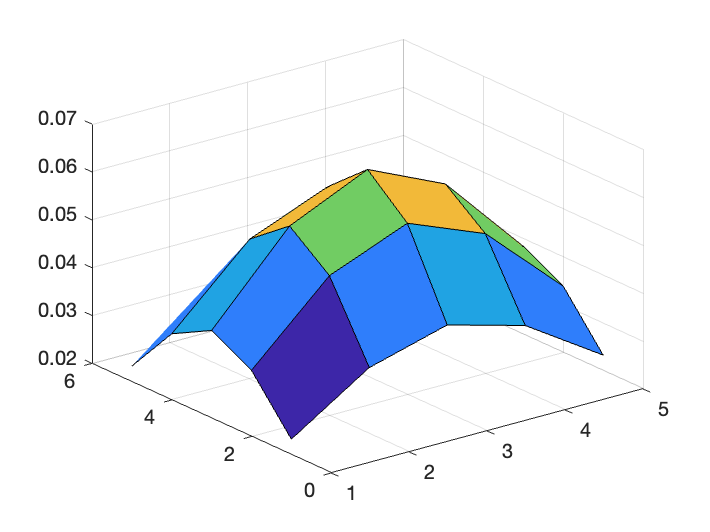

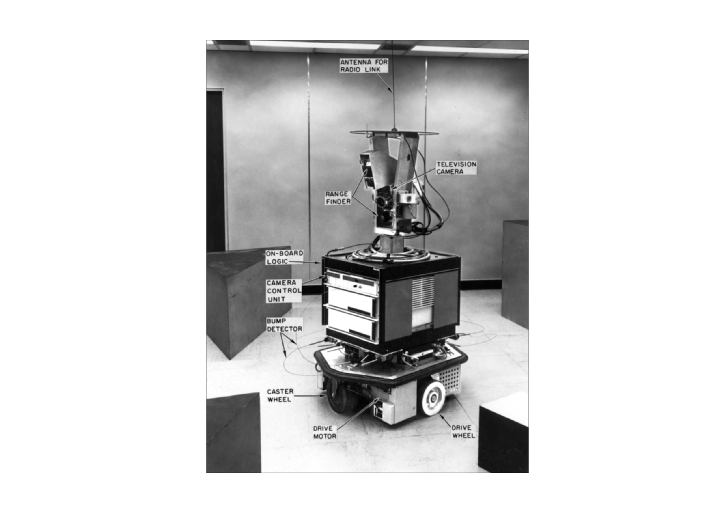

i = 1

mean_last = 33.8143

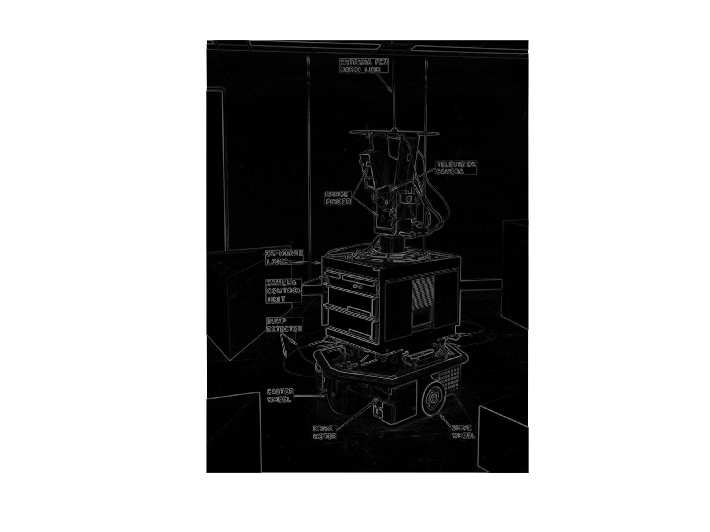

% fixed size=5; increasing std from 0.5 - 2
for i=(0.5:0.5:2)
    fname = "g3_std" + num2str(i)
    n_3 = gaussian_n(5, i, 1); % == gaussian_filter_3x3 
    g_3 = conv2(shakey, n_3, "same");
    show_image(g_3, fname); 
    g3_sobel = task1(g_3, sobelX, sobelY, 0, 0, fname + "_sobel_");
end  

**What is the effect of increasing the size of the Gaussian Filter (3x3 versus 5x5 for example)? What is the effect of changing the standard deviation *****s*****? Why do you see what you see?   **

All the filters are normalised, so the sum of filter matrix values are 1.

1. Increasing size of Gaussian Filter from 3 to 9 with fixed standard deviation (std=1) results in more blury and less noisy images  with thicker edges. Threshold values (mean value) drop from 42 to 38. Because filters are normalised, the dropping value means the intensity is smaller after averaging larger area. Edges and noises are both averaged within larger area so the noises get eliminated more and edges get blured (thicker).

2. Increasing standard deviation from 0.5 to 2 with fixed size =5 has similar effects of resulting in more blury and less noisy images with thicker edges. Threshold values (mean value) drop from 47 to 33. Because filters are normalised, the dropping value means the intensity is smaller after averaging more evenly within the area. Both edges and noises are getting smoother so the detected edges are thicker with larger std.

**Step 3 **

figure;
colors=['r','g','b','m',];
x = (1:1000);
for n=(3:2:9) 

    i = (n - 1) / 2;
    n_3 = N(0, 1, -i:1:i);
    n_3 = n_3 / sum(n_3); 

    n_3x3 = n_3' * n_3; 
    n_3x3 = n_3x3 / sum(n_3x3(:)); 

    tic;
    t1d=[];
    n_3_transpos=n_3';
    for j=x 
        gn_conv1 = conv2(conv2(shakey, n_3_transpos, "same"), n_3, "same");
        t1=toc;
        t1d = cat(1,t1d, t1);
    end
    avg1=t1/size(x, 2)*1000;
 
    tic;
    t2d=[];
    for j=x
        gn_conv2 = conv2(shakey, n_3x3, "same");
        t2=toc;
        t2d = cat(1,t2d, t2);
    end 
    avg2=t2/size(x, 2)*1000;
    clr = colors(i);

    hold on;
    plot(x,t1d,[clr,'--'],'DisplayName',"size"+num2str(n)+",1d:"+num2str(avg1));
    plot(x,t2d,[clr,'-'],'DisplayName',"size"+num2str(n)+",2d:"+num2str(avg2));
    
end
hold off;
title('Time: 1D vs 2D Gaussian conv');
xlabel('times');
ylabel('seconds');
lgd = legend('Location','northwest');
title(lgd,'Average (ms)');

As shown in Figures, for size 3 and size 5 Guassian filters, applying 2 1-D Guassian filters seperately requires more time than applying 1 2-D Guassian filter. As filter size grows larger to 7 and 9, applying 2D filters becomes slower than 1D. The time fluactuates ( time increases) are more noticeable as filter size gets larger for 1D filters.

The 2 results are slightly different because rounding float numbers. 2D Guassian filters are more accurate for only doing round operation once.

**Step 4**

laplacian

laplacian =      0     1     0
     1    -4     1
     0     1     0


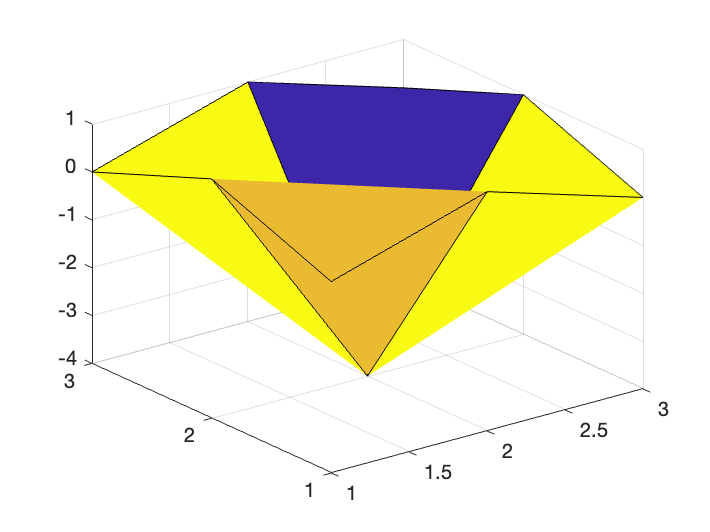

surf(laplacian); 
colormap("default"); 

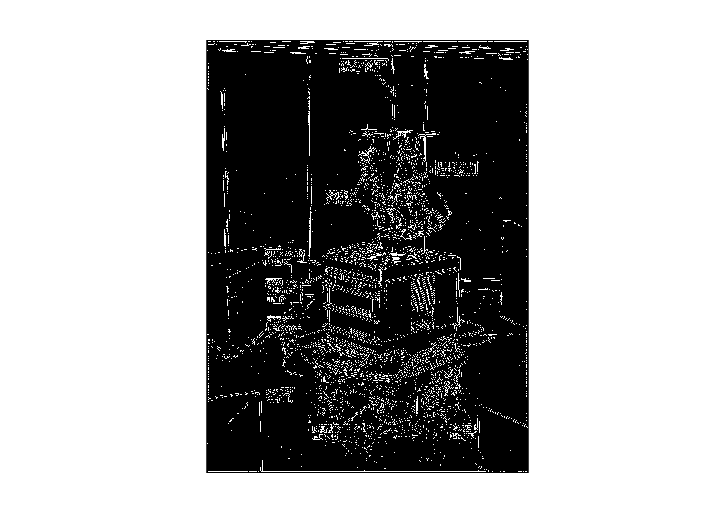


lap = conv2(shakey, laplacian);
edge_lap = edge(lap, "zerocross");
show_image(edge_lap, 'edge_lap');

Laplacian filter is sensitive to noises. Noises produce extra zero crossings.

**Task 3**

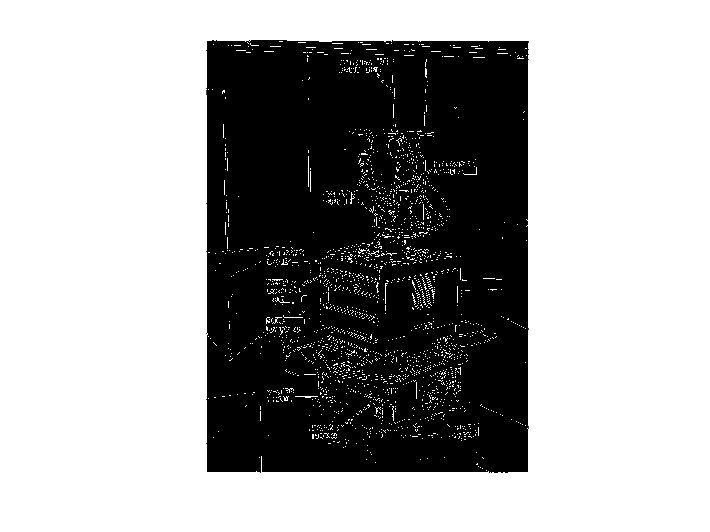

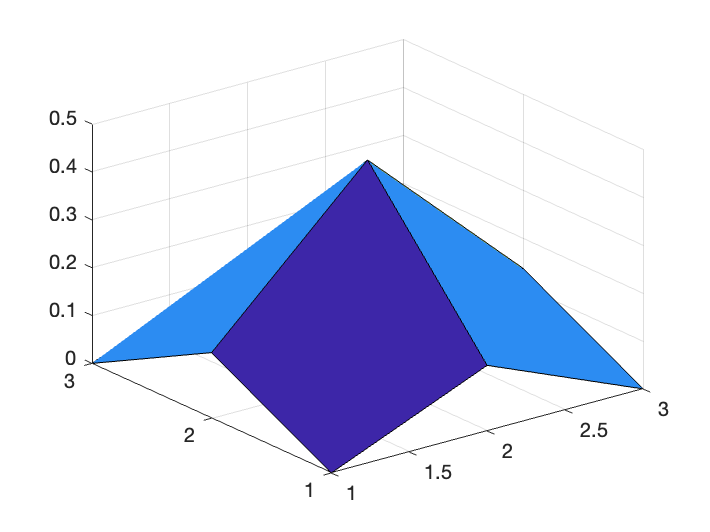

task3(shakey, 1, 3);
% task3(shakey, 1.4, 7);

**I mentioned the Laplacian of the Gaussian in the lecture. How could you combine the idea of the Laplacian operator with the idea of Gaussian smoothing? Try out your ideas. **

There're 2 ways of doing this.

Intuitive way is first apply the Gaussian filter to do smoothing then use Laplacian for edge detecting.

But mathmatically can be proven that, it is the same to apply Gaussian filter to Laplacian first then use the result to to convolution on original image. Because the size of kernal is way smaller than original images, this is more time efficient. 

Function `laplacian_of_gaussian_n` creates a LoG.

We can see from the results that, after applying LoG the edges become more clearer and noises get smoothed out. But at the same time, the position of the detected edges are shifted due to the smooth effects of Gaussians and some edges are blured or vanished.